clear all; clc; close all;

% Model of auditory primary cortex A1, following
% Loebel et al.(2007)
% https://doi.org/10.3389/neuro.01.1.1.015.2007

## Parameters

columns = 15;
cells_per_column = 200;
N_E = 100;
N_I = cells_per_column - N_E;

Tau_E = 0.001; % s
Tau_I = 0.001; % s

Tau_ref_E = 3*10^(-3); % s
Tau_ref_I = 3*10^(-3); % s

J_EE = [0.015,0.045,6,0.045,0.015]; % index goes from -2 to 2
J_IE = [0.0015,0.0035,0.5,0.0035,0.0015];
J_EI = -4; 
J_II = -0.5;

%sensory input distribution

lambda_C = 0.25;
alpha = 2;
delta = 5;

% synaptic resources
U = 0.5;
Tau_rec = 0.8; % s

%% Compact all parameters
params.N_E = N_E;
params.N_I = N_I;
params.columns = columns;
params.Tau_E = Tau_E;
params.Tau_I = Tau_I;
params.Taur_ref_E = Tau_ref_E;
params.Taur_ref_I = Tau_ref_I;
params.J_EE = J_EE;
params.J_EI = J_EI;
params.J_IE = J_IE;
params.J_II = J_II;
params.U = U;
params.Taur_rec = Tau_rec;
params.lambda_C = lambda_C;
params.alpha = alpha;
params.delta = delta;

params.brokencols = 9:15;
params.reorgweight = 2;%0.09;
max_t = 1;
loudness = 0;
randomize= false;
reconnect_twostep=false;

% Fig A
%params.brokencols = [];
%loudness = 5;
%max_t = 0.1;
%plottitle = 'Visualising inter-column connections';
% Fig B
%params.brokencols = 9;
%params.reorgweight = J_EE(4);
%loudness = 5;
%max_t = 0.1;
%plottitle  = 'Visualising inter-column connections';
% Fig C
%params.brokencols = 9;
%params.reorgweight = 0.09;
%loudness = 5;
%max_t = 0.1;
%plottitle  = append('Visualising inter-column connections ($J^1_{rewire}$=', num2str(params.reorgweight),')');
% Fig D
%params.brokencols = [9:15];
%params.reorgweight = 0.09;
%loudness = 5;
%max_t = 0.1;
%plottitle  = append('Visualising inter-column connections ($J^1_{rewire}$=', num2str(params.reorgweight),')');
% Fig E
%params.brokencols = [9:15];
%params.reorgweight = 2;
%reconnect_twostep=true;
%loudness = 5;
%max_t = 2;
%plottitle  = append('Visualising inter-column connections ($J^1_{rewire}$=', num2str(params.reorgweight),')');
% Fig F
randomize = true;
params.brokencols = [9:15];
params.reorgweight = 1;
loudness = 0;
max_t = 2;
plottitle  = 'Visualising inter-column connections ($J_{rewire}\sim U[0,1]$)';

columnconnections_exc = zeros(columns, columns);
columnconnections_exc(1:(columns+1):end) = J_EE(3)/2;
columnconnections_exc(2:(columns+1):(end - columns)) = J_EE(4);
columnconnections_exc(3:(columns+1):(end - 2*columns)) = J_EE(5);
columnconnections_exc = columnconnections_exc + columnconnections_exc';
for i = 1:length(params.brokencols)
    brokencol = params.brokencols(i);
    if (brokencol > 1)&&(brokencol < columns)
        if randomize

            for j = 1:10
                randtarget = brokencol;
                while randtarget == brokencol
                    randtarget = randi(10) + 5;
                end
                columnconnections_exc(brokencol,randtarget) = rand*params.reorgweight;
                columnconnections_exc(randtarget,brokencol) = columnconnections_exc(brokencol,randtarget);
            end

            columnconnections_exc(brokencol,brokencol-1) = rand*params.reorgweight;
            columnconnections_exc(brokencol-1,brokencol) = columnconnections_exc(brokencol,brokencol-1);
            columnconnections_exc(brokencol,brokencol+1) = rand*params.reorgweight;
            columnconnections_exc(brokencol+1,brokencol) = columnconnections_exc(brokencol,brokencol+1);

        else

            if reconnect_twostep
                columnconnections_exc(brokencol,max(brokencol-2,1)) = params.reorgweight/2;
                columnconnections_exc(max(brokencol-2,1),brokencol) = params.reorgweight/2;
                columnconnections_exc(brokencol,min(15,brokencol+2)) = params.reorgweight/2;
                columnconnections_exc(min(15,brokencol+2),brokencol) = params.reorgweight/2;
            end

            columnconnections_exc(brokencol,brokencol-1) = params.reorgweight;
            columnconnections_exc(brokencol-1,brokencol) = params.reorgweight;
            columnconnections_exc(brokencol,brokencol+1) = params.reorgweight;
            columnconnections_exc(brokencol+1,brokencol) = params.reorgweight;

        end


    end
end

columnconnections_inh = zeros(columns, columns);
columnconnections_inh(1:(columns+1):end) = J_IE(3)/2;
columnconnections_inh(2:(columns+1):(end - columns)) = J_IE(4);
columnconnections_inh(3:(columns+1):(end - 2*columns)) = J_IE(5);
columnconnections_inh = columnconnections_inh + columnconnections_inh';

params.columnconnections_exc = columnconnections_exc;
params.columnconnections_inh = columnconnections_inh;


## Background activity

e_max = 10; % Hz
e_min = -10; % Hz

% Create background noise
e_E = zeros(N_E,columns); % Hz
e_I = zeros(N_I,columns); % Hz

rng('default');
for ii = 1:columns
    init_e_E = 1:N_E;%rand(N_E,1); %Using fixed distribution of background noise to minimize interference
    init_e_I = 1:N_I;%rand(N_I,1);
    % scale
    highest_eE = max(init_e_E);
    lowest_eE = min(init_e_E);
    highest_eI = max(init_e_I);
    lowest_eI = min(init_e_I);
    e_E_range = max(init_e_E) - min(init_e_E);
    e_I_range = max(init_e_I) - min(init_e_I);
    
    actual_eE = (1/e_E_range)*(init_e_E*(e_max-e_min)+(e_min*highest_eE-e_max*lowest_eE));
    actual_eI = (1/e_I_range)*(init_e_I*(e_max-e_min)+(e_min*highest_eI-e_max*lowest_eI));

    e_E(:,ii) = sort(actual_eE);
    e_I(:,ii) = sort(actual_eI);
end

## Stimulus

% Create some random stimulus

s = cell(15,1);
nbeeps = 10;
fm = 0;
fletchermunson = (1./(1+abs(8-(1:15)))).^(fm/loudness);
maxtime = 0;

for i = 1:15
    t0 = 0;
    allbeeps = [];
    for j = 1:nbeeps
        soundstart = t0 + rand(1)*Tau_rec*2;
        soundstop = soundstart + 0.25;
        magnitude = loudness*fletchermunson(i);
        beep = [soundstart, soundstop, magnitude];
        t0 = soundstop;
        allbeeps = [allbeeps; beep];
        if t0 > maxtime
            maxtime = t0;
        end
    end
    s{i} = allbeeps;
end

s = cell(15,1);
s{8} = [0.01, 0.04, loudness];
maxtime = max_t;

## Initialise variables

%% Create neurons
E = rand(N_E,columns);
I = rand(N_I,columns);

%% Create synaptic resources
x = rand(size(E));
y = rand(size(I));

## Get initial conditions

% set stimulus to 0 and let the system converge
X0 = [E(:); I(:); x(:); y(:)];
t_rest = 2.5;%5*Tau_rec;
[t, X] = ode45(@(t,y) dXdt(t,y,params,0,e_E,e_I),[0,t_rest],X0);

[E,I,x,y] = reshape_X(X,[2,3,1], params);

E0 = E(:,:,end);
I0 = I(:,:,end);
x0 = x(:,:,end);
y0 = y(:,:,end);

## Solve ODE

t_span = [0, maxtime];
X0 = [E0(:); I0(:); x0(:); y0(:)];
[t, X] = ode45(@(t,y) dXdt(t,y,params,s,e_E,e_I),t_span,X0);

[E,I,x,y] = reshape_X(X,[1,3,2], params);

## Plot results

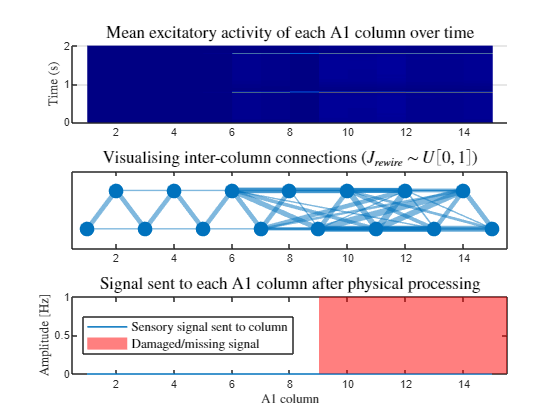


figure

%% Distributed inputs

damage_profile = zeros(15,1);
damage_profile(params.brokencols) = 1;
sensory_inputs = zeros(15,1);
sensory_inputs(8) = loudness;
distributed_sensory_inputs = get_distributed_sensory_inputs(sensory_inputs, lambda_C, alpha, delta);
distributed_sensory_inputs(params.brokencols) = 0;

subplot(3,1,3)
stairs(distributed_sensory_inputs)
hold on
if (length(params.brokencols)==1)
    h = fill([params.brokencols,params.brokencols+1, params.brokencols+1,params.brokencols],[0,0,loudness+1,loudness+1],'r','LineStyle','none');
    h.FaceAlpha = 0.5;
elseif (length(params.brokencols)>1)
    h = fill([params.brokencols(1),params.brokencols(end)+1, params.brokencols(end)+1,params.brokencols(1)],[0,0,loudness+1,loudness+1],'r','LineStyle','none');
    h.FaceAlpha = 0.5;
end
ylim([0, loudness+1])
title('Signal sent to each A1 column after physical processing','Interpreter','latex','FontSize',13)
xlim([0.5, 15.5])
xlabel('A1 column','Interpreter','latex','FontSize',10)
hold off
ylabel('Amplitude [Hz]','Interpreter','latex','FontSize',10)
legend('Sensory signal sent to column', 'Damaged/missing signal','Location','west','Interpreter','latex','FontSize',10)

%% Intercolumn network

subplot(3,1,2)
columnconnections_exc = columnconnections_exc - diag(diag(columnconnections_exc));
G=graph(columnconnections_exc);
LWidths = G.Edges.Weight;
LWidths(LWidths == params.J_EE(4)) = 0.7;
LWidths(LWidths == params.J_EE(5)) = 0.05;
LWidths(LWidths == 0.07) = 1.2;
LWidths(LWidths == 0.09) = 1.5;
LWidths(LWidths == 0.5) = 1.5;
LWidths(LWidths == 1) = 1.75;
LWidths(LWidths == 2) = 2;
LWidths = 5*LWidths;

p=plot(G, 'LineWidth',LWidths,'NodeLabel',{});
p.XData = 1:15;
p.YData = [repmat([1 3],1,7) 1];
p.MarkerSize = 10;
xlim([0.5, 15.5])

ylim([0 4])
xticks(2:2:14)
title(plottitle, 'Interpreter','latex','FontSize',13)

%% A1 response

subplot(3,1,1)
excitatory_average_per_column = mean(E, 3);
%image(excitatory_average_per_column', 'CDataMapping', "scaled")
[X_axis,Y_axis] = meshgrid(t,1:15);
surf(Y_axis',X_axis', excitatory_average_per_column, 'edgecolor','none')
view(2);
%colorbar
colormap('jet')
set(gca,'XDir','normal')
%xticks(1:1000:(length(t)))
%xticklabels(round(t(1:1000:(length(t))),2))
ylabel('Time (s)','Interpreter','latex','FontSize',10)
%xlabel('A1 column')
ylim([0, max(t)])
xlim([0.5, 15.5])
title('Mean excitatory activity of each A1 column over time','Interpreter','latex','FontSize',13)

function dXdt = dXdt(t,X,params,s,e_E,e_I)
    [E,I,x,y] = reshape_X_single_time_point(X,params);
   
    N_E = params.N_E;
    N_I = params.N_I;
    columns = params.columns;
    Tau_E = params.Tau_E;
    Tau_I = params.Tau_I;
    Tau_ref_E = params.Taur_ref_E;
    Tau_ref_I = params.Taur_ref_I;
    J_EE = params.J_EE;
    J_EI = params.J_EI;
    J_IE = params.J_IE;
    J_II = params.J_II;
    U = params.U;
    Tau_rec = params.Taur_rec;
    lambda_C = params.lambda_C;
    alpha = params.alpha;
    delta = params.delta;
    columnconnections_exc = params.columnconnections_exc;
    columnconnections_inh = params.columnconnections_inh;

    
    %% dEdt
    in_col_exci = sum(U*x.*E, 1)/N_E;
    between_col_exci = in_col_exci*columnconnections_exc;
    in_col_inhi = (J_EI/N_I)*sum(U*y.*I, 1);
    
    if (iscell(s))
        pure_input_per_column = lookup_all_sensory_inputs(t, s);
        distributed_input_per_column = get_distributed_sensory_inputs(pure_input_per_column, lambda_C, alpha, delta);
        distributed_input_per_column(params.brokencols) = 0;
        sensory_input_matrix = repmat(distributed_input_per_column', N_E, 1);
    else
        sensory_input_matrix = s;
    end
    
    relu = max((between_col_exci + in_col_inhi + e_E + sensory_input_matrix),0);

    dEdt= (1/Tau_E)*(-E + (1-Tau_ref_E*E).*relu);

    %% dIdt
    in_col_exci = sum(E, 1)/N_E;
    between_col_exci = in_col_exci*columnconnections_inh;

    in_col_inhi = (J_II/N_I)*sum(I, 1);
    relu = max((between_col_exci + in_col_inhi + e_I),0);

    dIdt= (1/Tau_I)*(-I + (1-Tau_ref_I*I).*relu);

    %% dxdt
    dxdt = (1-x)/Tau_rec - U*x.*E;
    %% dydt
    dydt = (1-y)/Tau_rec - U*y.*I;


    dXdt = [dEdt(:); dIdt(:); dxdt(:); dydt(:)];
end

function [E,I,x,y] = reshape_X_single_time_point(X,params)
% Gets a vector X of size (2*cells_per_column*columns, 1) and returns
% 4 arrays: E, I, x, y; each of them of size (N_i, columns), where i 
% is either E for excitatory cells or I for inhibitory cells.

    N_E = params.N_E;
    N_I = params.N_I;
    columns = params.columns; 
    % re-organize the vector X in its components
    cont = 1;
    E_col = X(1:N_E*columns);
    E = reshape(E_col,N_E,columns);
    cont = cont + size(E_col,1);
    
    I_col = X(cont:cont + N_I*columns-1);
    I = reshape(I_col,N_I,columns);
    cont = cont + size(I_col,1);
    
    x_col = X(cont:cont + N_E*columns-1);
    x = reshape(x_col,N_E,columns);
    cont = cont + size(x_col,1);

    y_col = X(cont: cont + N_I*columns-1);
    y = reshape(y_col,N_I,columns);
end
function [E,I,x,y] = reshape_X(X,order,params)
% Gets an array X of size (time_steps, 2*cells_per_column*columns) and returns
% 4 arrays: E, I, x, y; each of them of size (N_i, columns, time_steps), where i 
% is either E for excitatory cells or I for inhibitory cells.
% The order of the axes is given by the argument order:
% order = [2,3,1] -> (N_i, columns, time_steps). Useful when you need a
% 'photograph' of the variable at a single time_step.
%order = [1,3,2] -> (time_steps, columns, N_i. Useful for plotting the
%variable over time.

    N_E = params.N_E;
    N_I = params.N_I;
    columns = params.columns; 
    
    % Separate the vector X into E,I,x,y
    time_steps = size(X,1);
    cont = 1;
    
    E_col = X(:,cont:cont+N_E*columns-1);
    %E_col = X(1:time_steps*N_E*columns);
    cont = cont + size(E_col,2);
    I_col = X(:,cont:cont+N_I*columns-1);
    %I_col = X(1:time_steps*N_I*columns);
    cont = cont + size(I_col,2);
    x_col = X(:,cont:cont+N_E*columns-1);
    %x_col = X(1:time_steps*N_E*columns);
    cont = cont + size(x_col,2);
    y_col = X(:,cont:cont+N_I*columns-1);
    %y_col = X(1:time_steps*N_I*columns);

    % reshape each tensor in 3 dimensions, one for time, other for columns,
    % other for cells in the column
    E = reshape(E_col,time_steps,N_E,columns);
    I = reshape(I_col,time_steps,N_I,columns);
    x = reshape(x_col,time_steps,N_E,columns);
    y = reshape(y_col,time_steps,N_I,columns);

    % Re-organize the axes so that each tensor has the shape (cells_per_column,
    % columns, t)
    E = permute(E,order);
    I = permute(I,order);
    x = permute(x,order);
    y = permute(y,order);
end

function full_distributed_sensory_grid = get_full_distributed_sensory_grid(t_array,all_sensory_inputs, lambda_C, alpha, delta)

    full_sensory_grid_temp = zeros(length(all_sensory_inputs),length(t_array));
    for i = 1:length(t_array)
        full_sensory_inputs = lookup_all_sensory_inputs(t_array(i), all_sensory_inputs);
        full_sensory_grid_temp(:,i) = get_distributed_sensory_inputs(full_sensory_inputs, lambda_C, alpha, delta);
    end
    full_distributed_sensory_grid = full_sensory_grid_temp;
end

function full_sensory_grid = get_full_sensory_grid(t_array,all_sensory_inputs)

    full_sensory_grid_temp = zeros(length(all_sensory_inputs),length(t_array));
    for i = 1:length(t_array)
        full_sensory_grid_temp(:,i) = lookup_all_sensory_inputs(t_array(i), all_sensory_inputs);
    end
    full_sensory_grid = full_sensory_grid_temp;
end

function distributed_sensory_inputs = get_distributed_sensory_inputs(sensory_inputs, lambda_C, alpha, delta)
    % For an array of sensory inputs (where the i-th entry is the power
    % of the i-th tone), get the distribution of the tone strength across
    % the A1 columns
    
    sensory_inputs = sensory_inputs(:); % forces to column just in case supplied as row
    n_tones = length(sensory_inputs); % number of tones (which should equal number of A1 columns)
    distributed_sensory_inputs_temp = zeros(n_tones, 1);
    
    for Q = 1:n_tones
        A = sensory_inputs(Q); % the power of the tone
        lambda_S = get_lambda_S(A, lambda_C, alpha, delta); % the exponential decay rate of the tone
        distance_of_each_target_A1_column_from_this_tone = abs(Q - (1:n_tones));
        exponent = distance_of_each_target_A1_column_from_this_tone(:)/lambda_S;
        
        distributed_sensory_inputs_temp = distributed_sensory_inputs_temp + A*exp(-exponent); % cumulative sum of the distributed inputs
    end
    
    distributed_sensory_inputs = distributed_sensory_inputs_temp; 
    
end

function lambda_S = get_lambda_S(A, lambda_C, alpha, delta)
    
    if (A <= alpha)
        lambda_S = lambda_C;
    else
        lambda_S = lambda_C + (A-alpha)/delta;
    end

end

function all_sensory_input_loudness = lookup_all_sensory_inputs(t, all_sensory_inputs)

    sensoryinputattimeT = zeros(size(all_sensory_inputs,1), 1);
    for i = 1:size(all_sensory_inputs,1) 
        sensoryinputattimeT(i,1) = lookup_sensory_input(t, all_sensory_inputs{i});   
    end
    all_sensory_input_loudness = sensoryinputattimeT;
end

function sensory_input_loudness = lookup_sensory_input(t, sensory_input_matrix)
    % For a given time t, and a sensory_input_matrix for some tone, returns the total
    % loudness being injected at that time
    
    sensory_input_loudness_runnningtotal = 0;
    for i =1:size(sensory_input_matrix,1)
        if (t >= sensory_input_matrix(i,1)) && (t < sensory_input_matrix(i,2))
            sensory_input_loudness_runnningtotal = sensory_input_loudness_runnningtotal + sensory_input_matrix(i,3); 
        end
    end
    sensory_input_loudness = sensory_input_loudness_runnningtotal;
    
end